# Analise das distribuições no disco rotor

### Em voo pairado

clc
clear
close all

mass_payload = 20;

vehicle_position = [0; 0; 5000];
vehicle_velocity = [0; 0; 0];
vehicle_orientation = [0; 0; 0];

Nb = 2;
Span = 1;
RootBladeDistance = 0.1;
theta = 10;
twist_rate = 0;
chord = 0.17;

RPM = 1000;

induced_velocity = 0;

azimutal_points = 300;
No_elements = 100;

blade_integrator = 'Trapezoidal'; %  'Boole';  % 'Rectangle'; % 'Simpson';

sim_init_rotor_simulation
 [F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE)

F_rotor =     0.0000
   -0.0000
  635.3559


T_rotor =   528.0443
         0
   -0.0000


rotor_distribution_data =   RotorAzimutalDistribution with properties:

    blade_distribution_data: [1×300 BladeDistribution]
          azimutal_position: [300×1 double]


#### Velocidade Tangencial

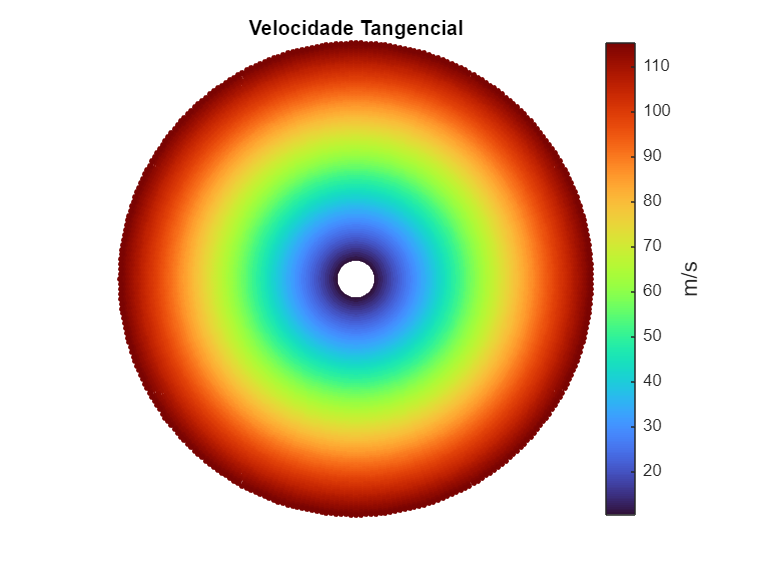

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_T;
end
polarPlot(azimutes, rho, values, "Velocidade Tangencial", "m/s", "./studies/rotor_analysis/sim_A/U_T.png")

#### Velocidade Radial

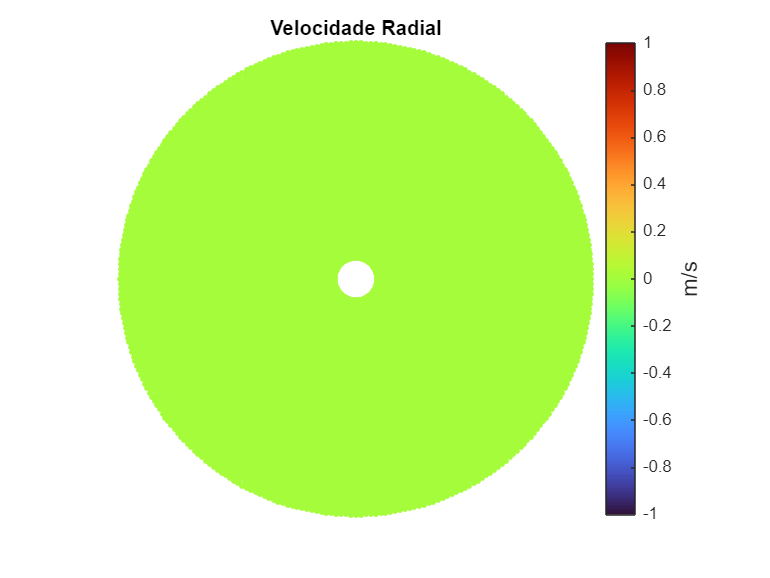

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_R;
end
polarPlot(azimutes, rho, values, "Velocidade Radial", "m/s", "./studies/rotor_analysis/sim_A/U_R.png")

#### Velocidade Vertical

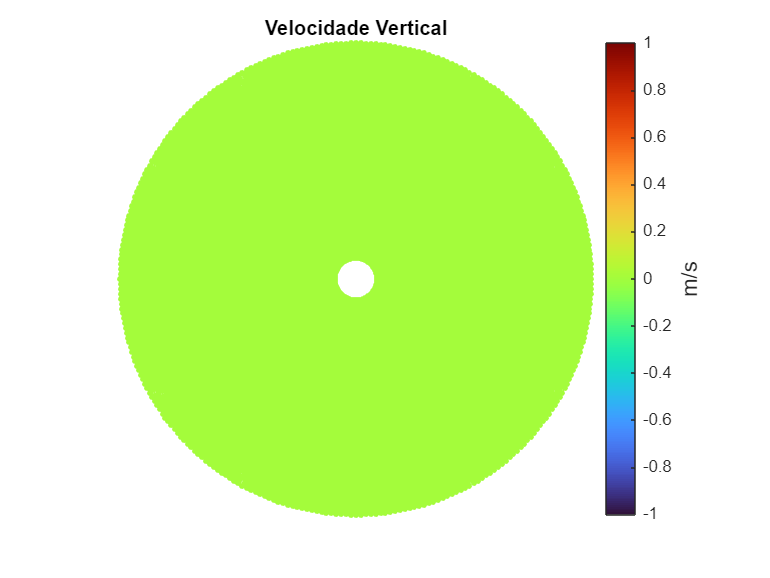

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_P;
end
polarPlot(azimutes, rho, values, "Velocidade Vertical", "m/s", "./studies/rotor_analysis/sim_A/U_P.png")

#### Modo de escoamento

aqui o modo do escoamento só tem duas possibilidades 0 ou 1, onde 0 significa normal e 1 invertido

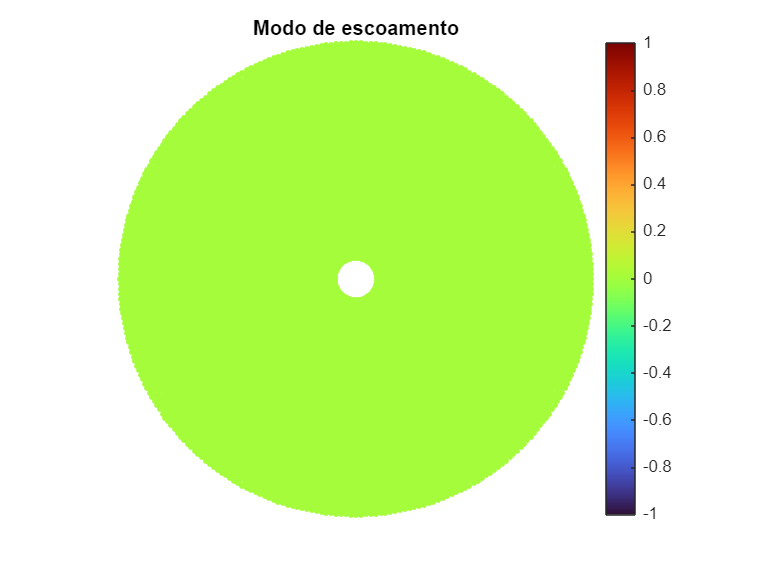

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).flow_mode;
end
polarPlot(azimutes, rho, values, "Modo de escoamento", "", "./studies/rotor_analysis/sim_A/flow_mode.png")

#### Número de Reynolds

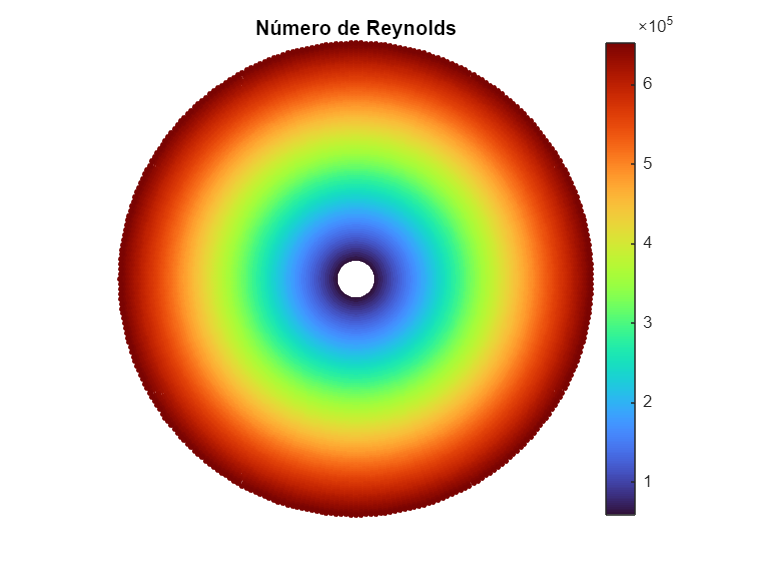

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Re;
end
polarPlot(azimutes, rho, values, "Número de Reynolds", "", "./studies/rotor_analysis/sim_A/Re.png")

#### Número de Mach

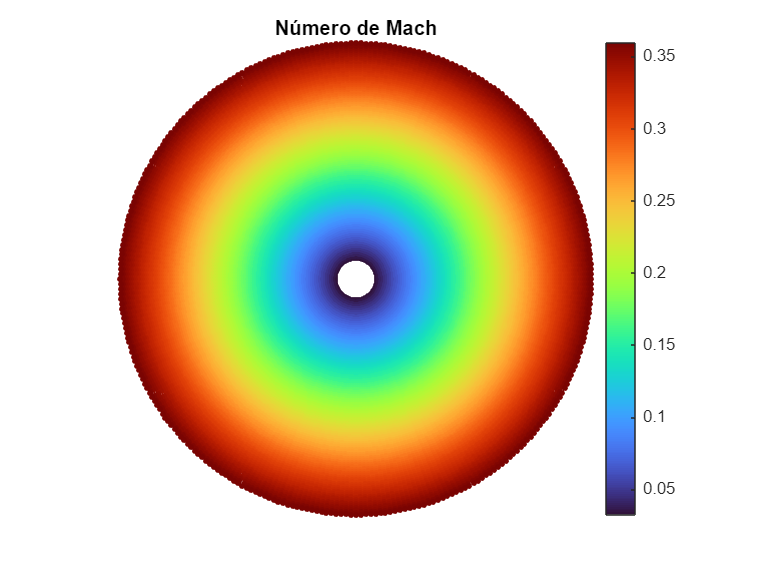

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Ma;
end
polarPlot(azimutes, rho, values, "Número de Mach", "", "./studies/rotor_analysis/sim_A/mach.png")

#### Ângulo de picada

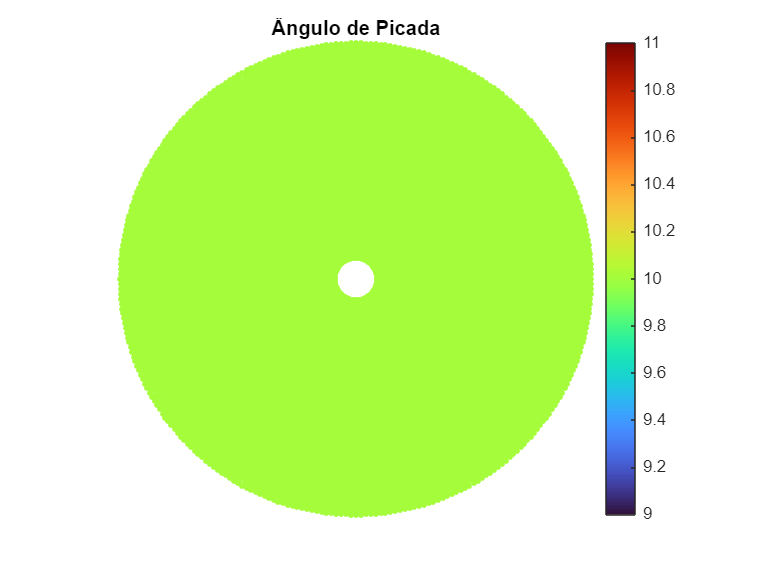

for i=1:length(azimutes)
    values(i, :) = BLADE.theta;
end
polarPlot(azimutes, rho, values, "Ângulo de Picada", "", "./studies/rotor_analysis/sim_A/theta.png")

#### Ângulo de incidência

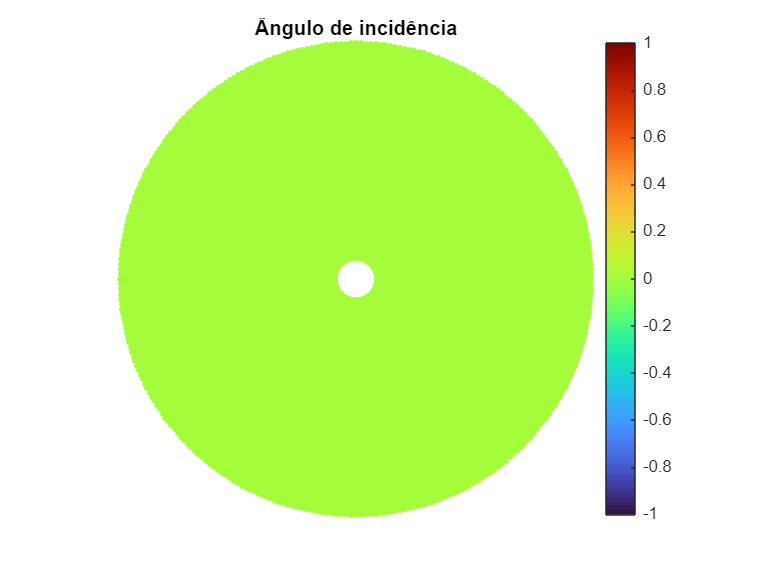

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).phi;
end
polarPlot(azimutes, rho, values, "Ângulo de incidência", "", "./studies/rotor_analysis/sim_A/phi.png")

#### Ângulo de ataque

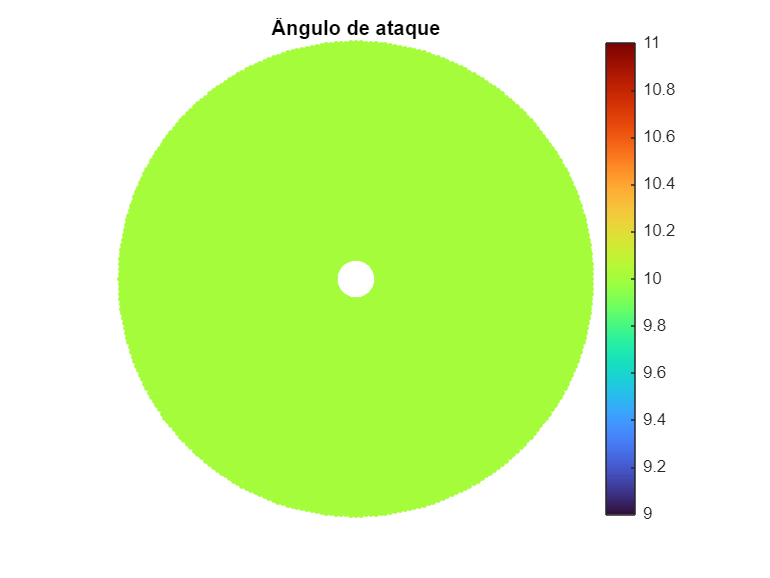

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).alpha;
end
polarPlot(azimutes, rho, values, "Ângulo de ataque", "", "./studies/rotor_analysis/sim_A/alpha.png")

#### Coeficiente de Sustentação

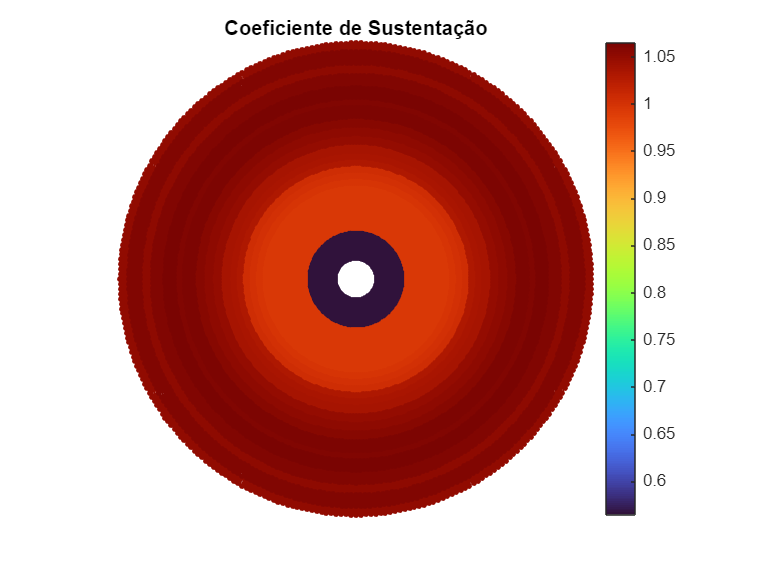

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cl;
end
polarPlot(azimutes, rho, values, "Coeficiente de Sustentação", "", "./studies/rotor_analysis/sim_A/cl.png")

#### Coeficiente de Arrasto

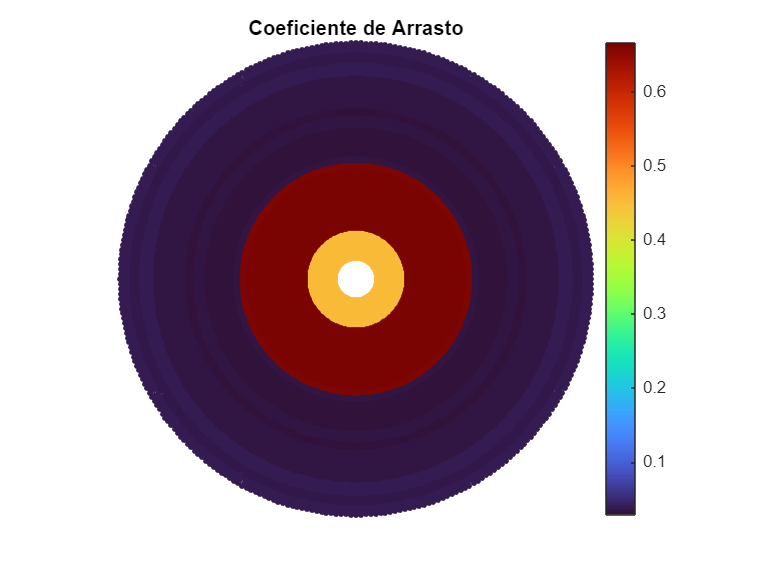

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cd;
end
polarPlot(azimutes, rho, values, "Coeficiente de Arrasto", "", "./studies/rotor_analysis/sim_A/cd.png")

#### Força em X - referencial do aerodinâmico

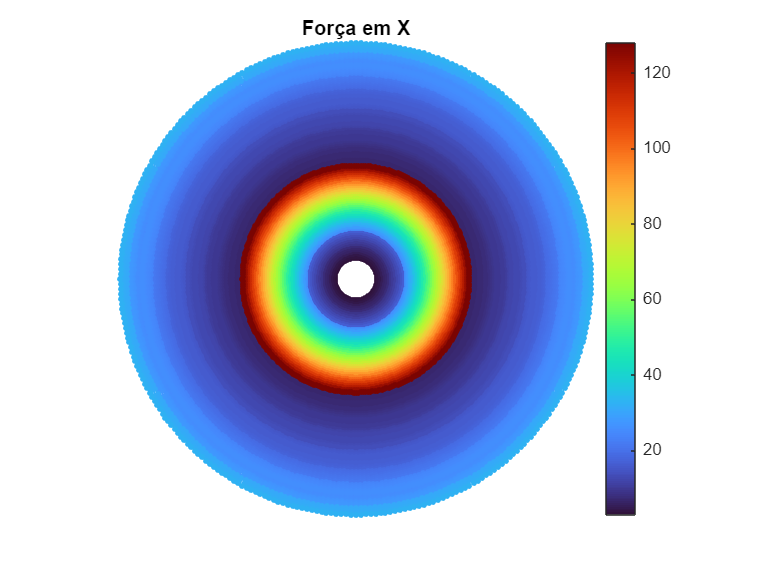

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(1, :);
end
polarPlot(azimutes, rho, values, "Força em X", "","./studies/rotor_analysis/sim_A/dFx_a.png")

#### Força em Y - referencial do aerodinâmico

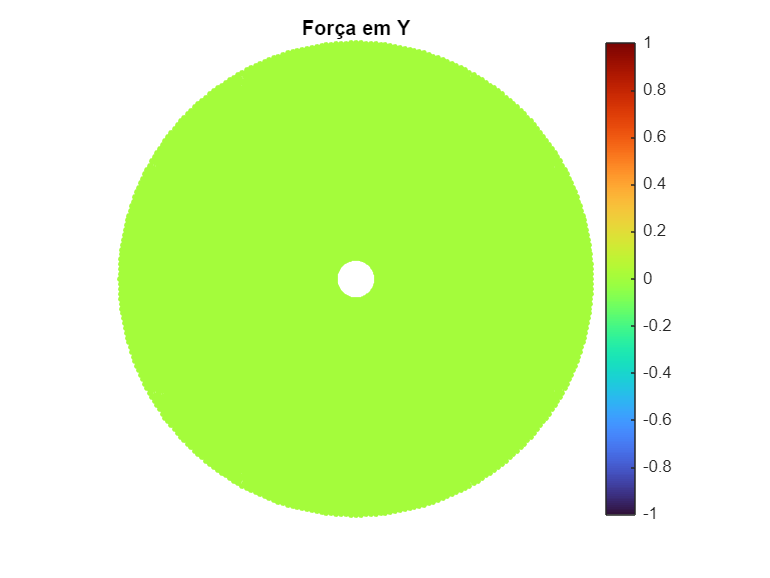

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(2, :);
end
polarPlot(azimutes, rho, values, "Força em Y", "", "./studies/rotor_analysis/sim_A/dFy_a.png")

#### Força em Z - referencial do aerodinâmico

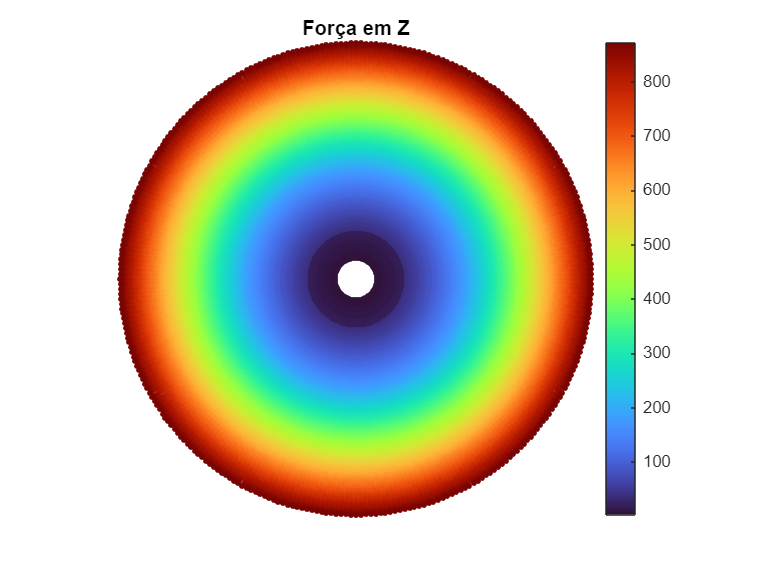

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(3, :);
end
polarPlot(azimutes, rho, values, "Força em Z", "", "./studies/rotor_analysis/sim_A/dFz_a.png")

#### Força em X - referencial do rotor

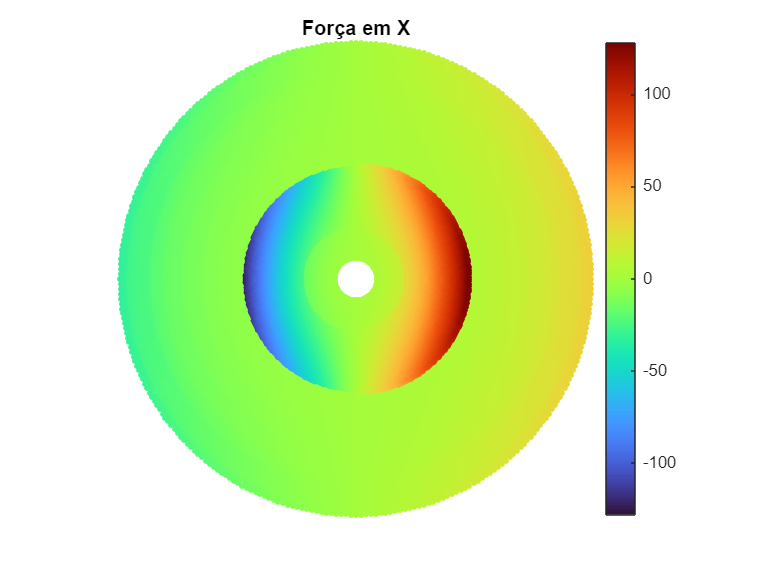

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(1, :);
end
polarPlot(azimutes, rho, values, "Força em X", "", "./studies/rotor_analysis/sim_A/dFx_r.png")

#### Força em Y - referencial do rotor

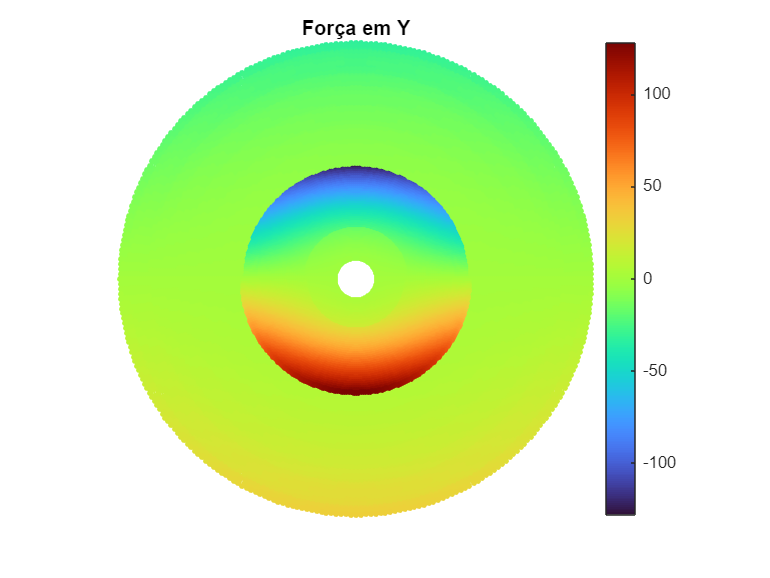

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(2, :);
end
polarPlot(azimutes, rho, values, "Força em Y", "", "./studies/rotor_analysis/sim_A/dFy_r.png")

#### Força em Z - referencial do rotor

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(3, :);
end
polarPlot(azimutes, rho, values, "Força em Z", "", "./studies/rotor_analysis/sim_A/dFz_r.png")